# HW 9 - Ch 12 - Iterative Methods

## Problem 1 -

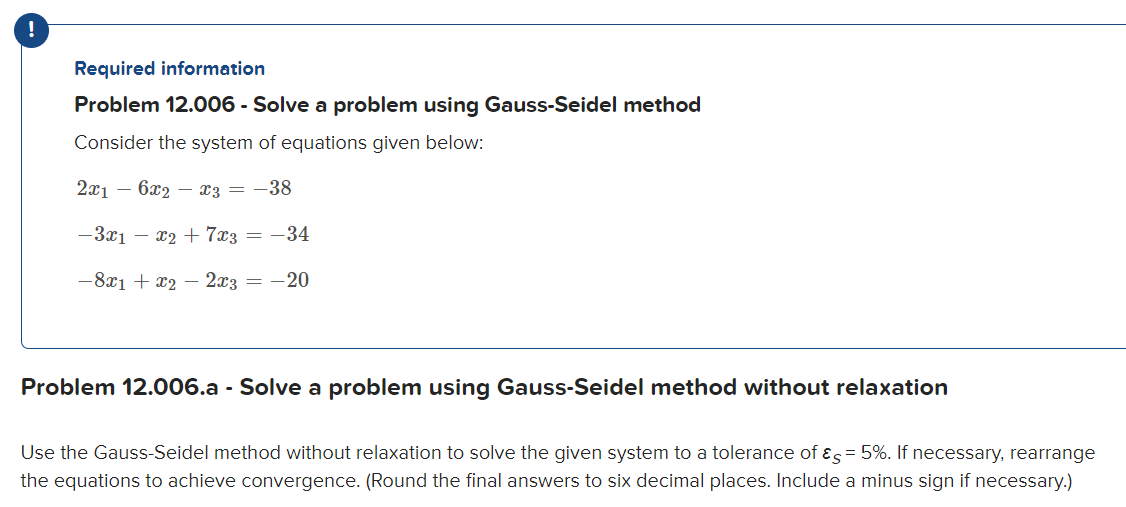

A = [2 -6 -1; -3 -1 7; -8 1 -2];
b = [-38;-34;-20];
es = 5;
format long;
help GaussSeidel

  GaussSeidel: Gauss Seidel method
  [x,ea,iter] = GaussSeidel(A,b,es,maxit): Gauss Seidel without relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



[x,ea,iter] = GaussSeidel(A,b,es) % diverges: huge #s

x = 1.0e+49 *

  -0.487077645191889
   0.539948058111492
   2.218284609823301


ea =      1.260069202452117e+02


iter =     50



% Now gotta rearrange so converges
%   Get it diagonally dominant

A_dd = [A(3,:); A(1,:); A(2,:)];
b_dd = [b(3); b(1); b(2)];

[x_dd,ea_dd,iter_dd] = GaussSeidel(A_dd,b_dd,es)

x_dd =    4.004659155328798
   7.991679657974300
  -1.999191839434186


ea_dd =    2.922791154575519


iter_dd =      3



% Double check
C = A\b

C =      4
     8
    -2


## Problem 2 -

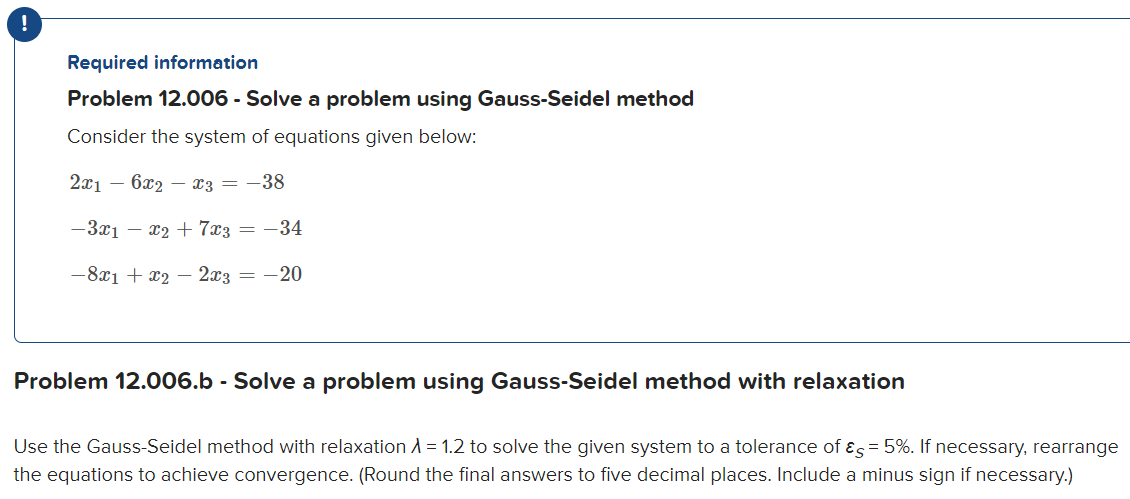

A = [2 -6 -1; -3 -1 7; -8 1 -2];
b = [-38;-34;-20];
lamda = 1.2;
es = 5;

format long;
help GaussSeidelRelax

  GaussSeidel: Gauss Seidel method with relaxation
  [x,ea,iter] = GaussSeidelRelax(A,b,lambda,es,maxit): Gauss Seidel with relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  lambda = relation factor (default = 1)
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



[x,ea,iter] = GaussSeidelRelax(A,b,lamda,es) % diverges: huge #s

x = 1.0e+55 *

   0.230350014345215
  -1.641864797050903
  -2.071838821154675


ea =      1.049576116911719e+02


iter =     50



% Need to rearrange for convergence then
[x_dd,ea_dd,iter_dd] = GaussSeidelRelax(A_dd,b_dd,lamda,es)

x_dd =    4.012225382137928
   8.027261339690046
  -1.979006985096710


ea_dd =    3.595466334278193


iter_dd =      6


## Problem 3 - 

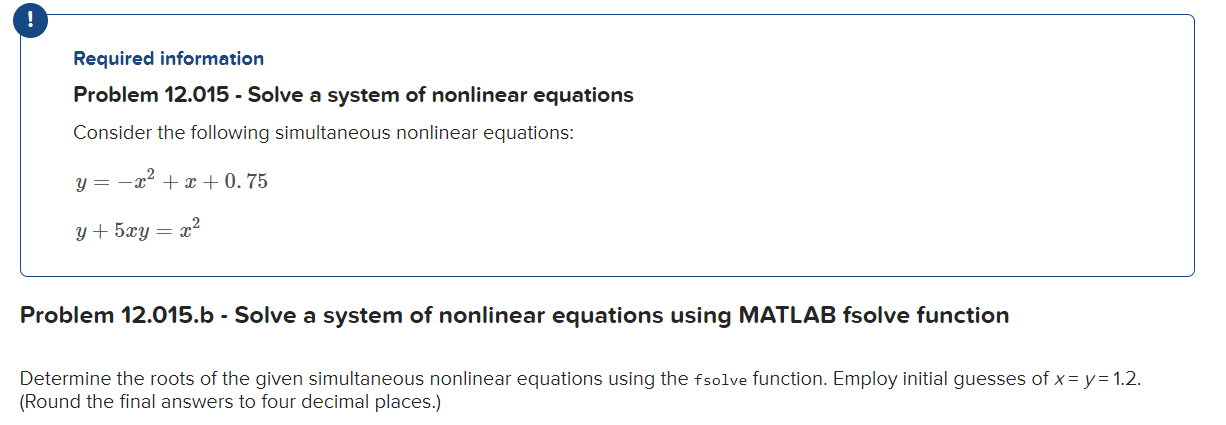

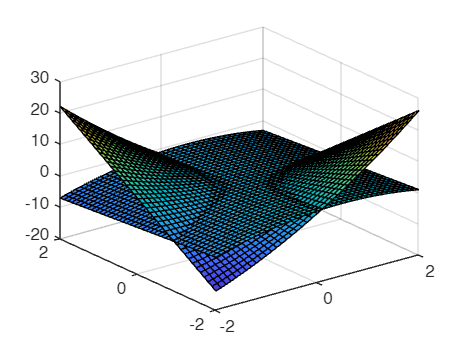

hold off;

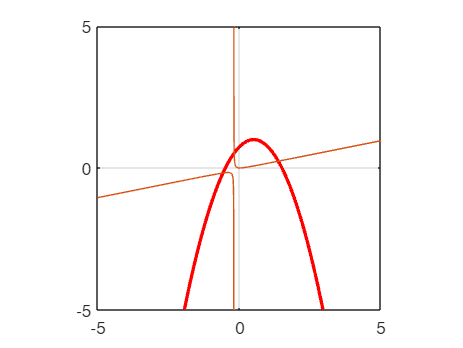

fimplicit(@(x, y) -x.^2+x+0.75-y, 'LineWidth', 2, 'Color', 'r');
hold on;
grid on;
axis equal;
fimplicit(@(x,y) y+5*x.*y-x.^2);
hold off;


help fsolve

 fsolve solves systems of nonlinear equations of several variables.
 
    fsolve attempts to solve equations of the form:
              
    F(X) = 0    where F and X may be vectors or matrices.   
 
    fsolve implements three different algorithms: trust region dogleg,
    trust region, and Levenberg-Marquardt. Choose one via the option
    Algorithm: for instance, to choose trust region, set OPTIONS =
    optimoptions('fsolve','Algorithm','trust-region'), and then pass
    OPTIONS to fsolve.
     
    X = fsolve(FUN,X0) starts at the matrix X0 and tries to solve the 
    equations in FUN.  FUN accepts input X and returns a vector (matrix) of 
    equation values F evaluated at X. 
 
    X = fsolve(FUN,X0,OPTIONS) solves the equations with the default
    optimization parameters replaced by values in OPTIONS, an argument
    created with the OPTIMOPTIONS function.  See OPTIMOPTIONS fo


% fu = -x1^2+x1+0.75-x2; % set = 0
% fv = x2+5*x1*x2-x1^2;
x0 = [2 3.5];
es_newt = 0.0001; % desired percent relative error
maxit_newt = 50;  % maximum iterations

[x_newt, f_newt, ea_newt, iter_newt] = newtmult(@jfreact2, x0) % literally all it needs is x. u & v given

x_newt =    1.372065405827350   2.872065405827350
   0.239501927959209   1.739501927959210


f_newt = 1.0e-06 *

  -0.006441097349930
  -0.281442387173314


ea_newt = 1.0e-04 *

   0.131617234122491   0.018121613329844


iter_newt =      5




FUN = @(x) [-x(1)^2+x(1)+0.75-x(2);x(2)+5*x(1)*x(2)-x(1)^2];
%FUN = @(x) [-x(1)*x(1)+x(1)+0.5-x(2);x(1)*x(1)-x(2)-5*x(1)*x(2)];

 
X0 = [1.2 1.2];

[X,FVAL] = fsolve(FUN,X0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


X =    1.372065408460267   0.239501928851969


FVAL = 1.0e-08 *

  -0.548494177854408
   0.294522295440913



[x1, x2] = meshgrid(-2:0.1:2, -2:0.1:2);

% Evaluate g(x1, x2) over the grid
G = -x1.^2+x1+0.75-x2;
H = x1.^2-5*x1.*x2-x2;

% Plot 3D surface
figure;
surf(x1, x2, G);
hold on;
surf(x1, x2, H);